# 数据可视化 小组Project

钟诚        16307110259

周璐鹿    15307110349

张奕朗    16307130242

清理运行环境

clear
clc
close all

## 局部仿射变换测试

读取测试图片

testImg = imread('../test_images/ape.png');
testImg = double(testImg) / 256;

反向仿射变换：将图像中部两个$32\times 32$的矩形分别顺时针、逆时针旋转${45}^{\circ }$

[H,W] = size(testImg,[1,2]);
testTransMap = zeros(H,W);
testTransMap(H/2-31:H/2,W/2-31:W/2) = 1;
testTransMap(H/2+1:H/2+32,W/2+1:W/2+32) = 2;
testTransform = cell(1,2);
testTransform{1} = [1/sqrt(2), 1/sqrt(2), 0 ;
                   -1/sqrt(2), 1/sqrt(2), 0 ;
                       0     ,     0    , 1 ];
testTransform{2} = [1/sqrt(2),-1/sqrt(2), 0 ;
                    1/sqrt(2), 1/sqrt(2), 0 ;
                       0     ,     0    , 1 ];

调用函数，进行测试

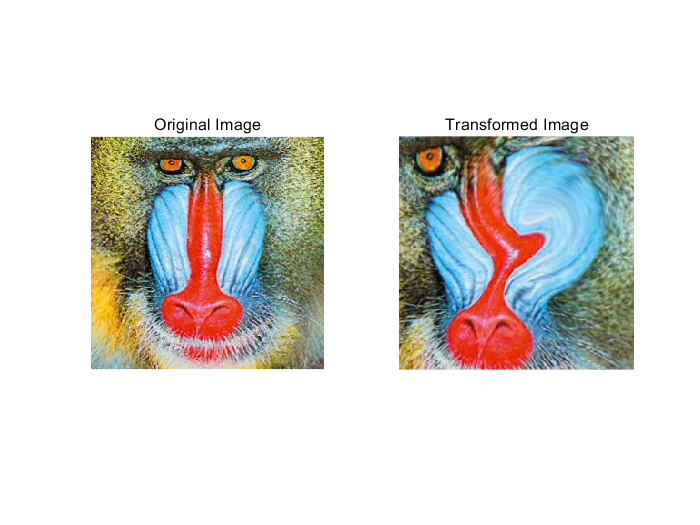

localAffine_inv(testImg,testTransform,testTransMap,'dist_e',2,'visualize',true);

## 应用：人脸变换

读取原本的图像和，并标记相应的区域

A = imread('../test_images/B.jpg');
A = A(1:545,:,:);
A = double(A) / 256;
A_control = {[160, 165, 170, 205, 220, 230], [157, 165, 170, 245, 260, 275], [160, 195, 225, 237, 253], [200,220,220,260]};
% 1 - square(4), 2 - triangle(5), 3 - diamond(6), 4 - Trapezoid(6)
A_style = {3,3,2,1};

读取待改变的图像

goal = imread('../test_images/dlrb.jpg');
goal = double(goal) / 256;
goal_control = {[230, 250, 265, 165, 200, 230], [225, 245, 260, 265, 295, 330], [225, 320, 220, 250, 280],[330, 365, 210, 295]};
goal_style = {3,3,2,1};

计算相关transform矩阵

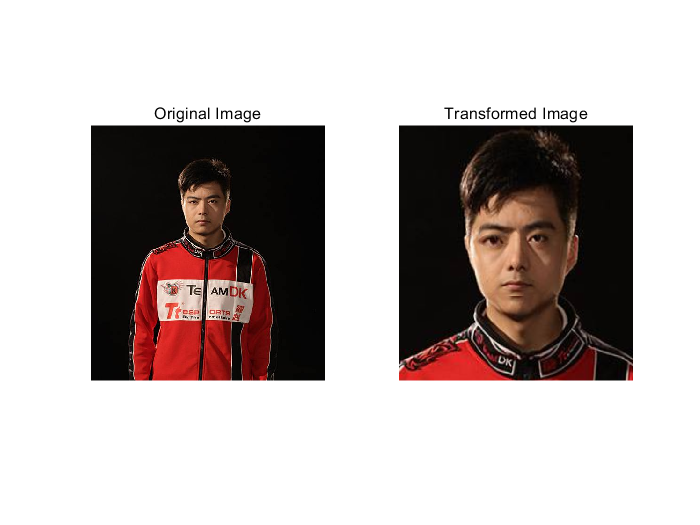

shape_A = size(A);
shape_goal = size(goal);
transMap = form_transMap(shape_goal, goal_control, goal_style);
transA = form_transMap(shape_A, A_control, A_style);
for i = 1:size(goal_control,2)
    transform{i} = form_transform(shape_A, shape_goal, A_control{i}, goal_control{i}, goal_style{i});
end
localAffine_inv(A,transform,transMap);